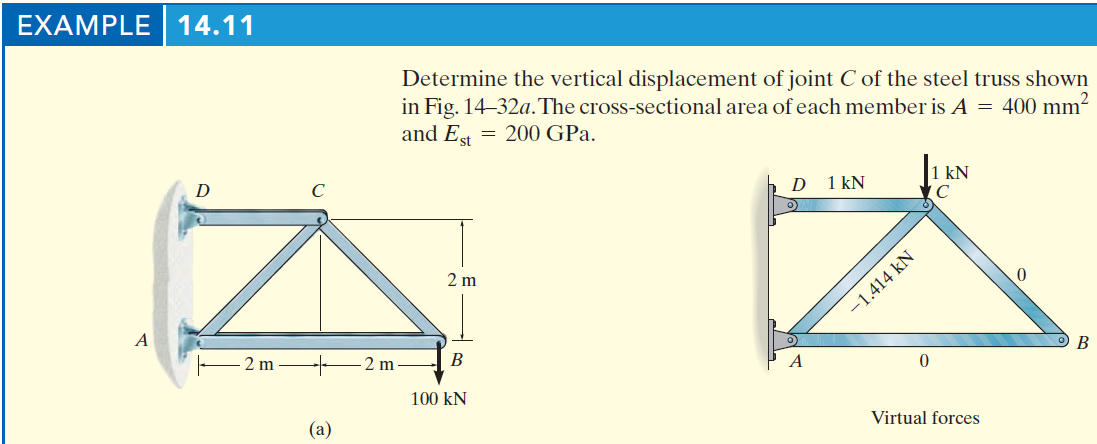

# member data

u = symunit;
E = 200*u.GPa;
A = 400*u.mm^2;
theta = atand(sym(1))*u.deg;

# truss

t = Truss;
t = t.add('load', 'reaction', {'Rax' 'Ray'}, [0 0]);
t = t.add('load', 'reaction', {'Rdx' 'Rdy'}, [0 2]*u.m);
t = t.add('load', 'applied', [0 -100]*u.kN, [4 0]*u.m);
t = t.add('joint', 'A', [0 0]);
t = t.add('joint', 'B', [4 0]*u.m);
t = t.add('joint', 'C', [2 2]*u.m);
t = t.add('joint', 'D', [0 2]*u.m);
t = t.add('member', 'Fab', [0 0], [4 0]*u.m, E, A);
t = t.add('member', 'Fac', [0 0], [2 2]*u.m, E, A);
t = t.add('member', 'Fbc', [4 0]*u.m, [2 2]*u.m, E, A);
t = t.add('member', 'Fcd', [2 2]*u.m, [0 2]*u.m, E, A);

# solution

[us fs rs ua fa ra] = t.solve('factor'); %#ok
ua_vpa = vpa(ua, 4) %#ok

$$ua\_vpa = \left(\begin{array}{cc} u_{1} & 0\\ v_{1} & 0\\ u_{2} & -5.0\,\mathrm{mm}\\ v_{2} & -29.14\,\mathrm{mm}\\ u_{3} & 5.0\,\mathrm{mm}\\ v_{3} & -12.07\,\mathrm{mm}\\ u_{4} & 0\\ v_{4} & 0 \end{array}\right)$$

fa_vpa = vpa(fa, 5) %#ok

$$fa\_vpa = \left(\begin{array}{cc} \mathrm{Fab} & -100.0\,\mathrm{kN}\\ \mathrm{Fac} & -141.42\,\mathrm{kN}\\ \mathrm{Fbc} & 141.42\,\mathrm{kN}\\ \mathrm{Fcd} & 200.0\,\mathrm{kN} \end{array}\right)$$

ra

$$ra = \left(\begin{array}{cc} \mathrm{Rax} & 200\,\mathrm{kN}\\ \mathrm{Ray} & 100\,\mathrm{kN}\\ \mathrm{Rdx} & -200\,\mathrm{kN}\\ \mathrm{Rdy} & 0 \end{array}\right)$$

clear ua_vpa fa_vpa;